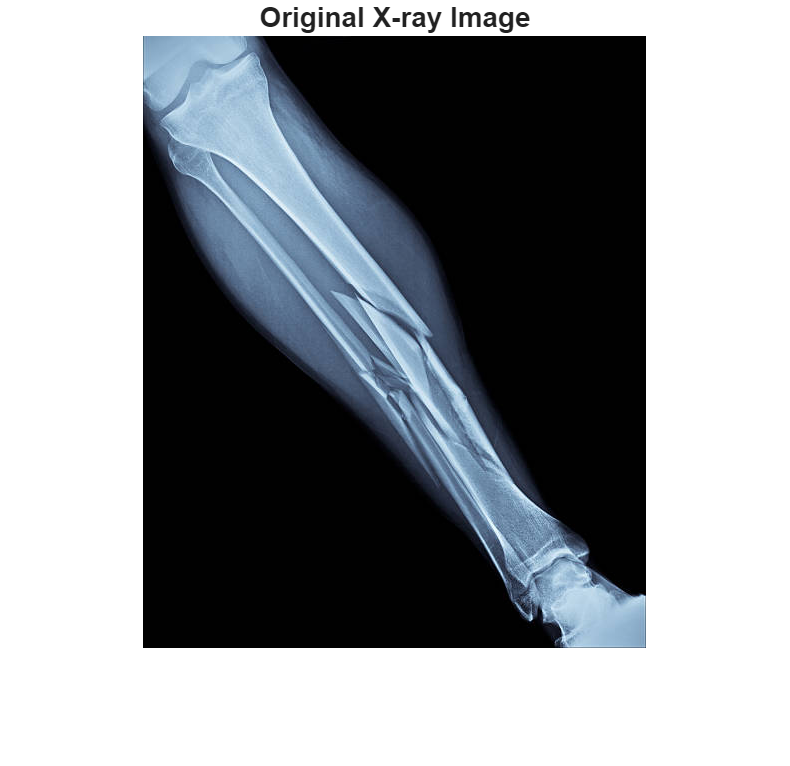

%% Detection of Bone Fracture Using Image Processing
% Champak Kumar Sinha - Amity University Kolkata

clc; clear; close all;

%% Step 1: Select Input Image
[filename, filepath] = uigetfile({'*.png;*.jpg'}, 'Select an X-ray image');
if isequal(filename,0)
    disp('No file selected.'); return;
end
I = imread(fullfile(filepath, filename));
imshow(I); title('Original X-ray Image');

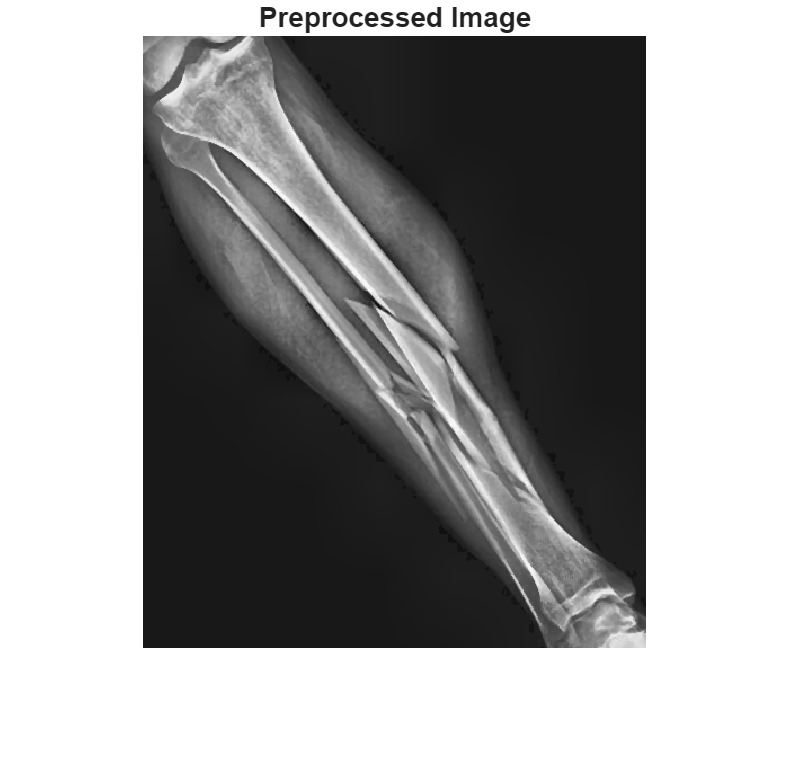


%% Step 2: Preprocess Image
I_prep = preprocess(I);
figure; imshow(I_prep); title('Preprocessed Image');

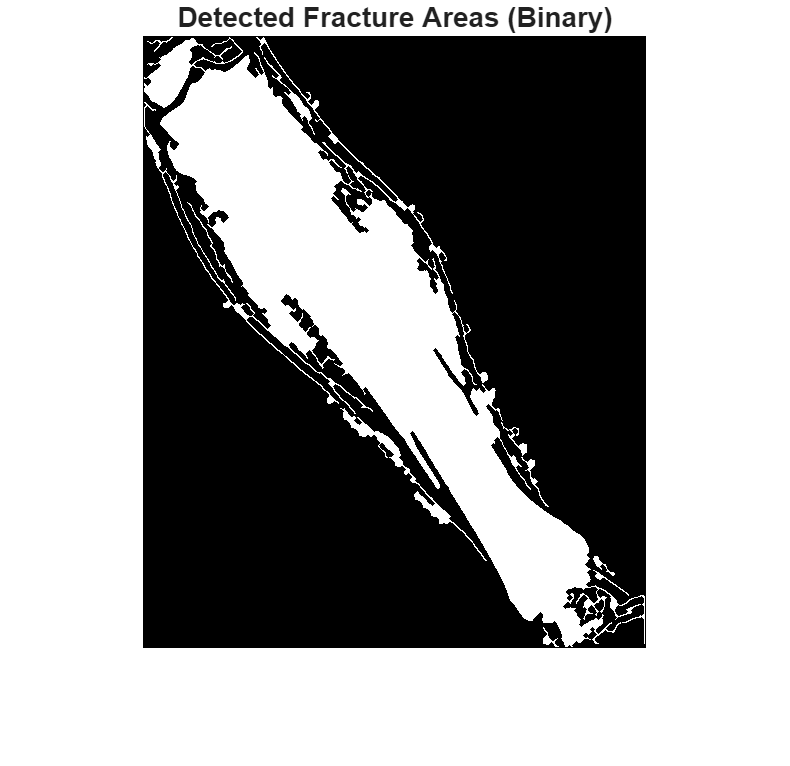


%% Step 3: Detect Possible Fracture Regions
BW = detect_fracture(I_prep);
figure; imshow(BW); title('Detected Fracture Areas (Binary)');


%% Step 4: Visualize and Save Result
outputPath = fullfile('..','results','example_outputs',['Detected_' filename]);
visualize_result(I, BW, outputPath);

%% Step 5: Completion Message
fprintf('✅ Fracture detection completed for %s\nResult saved to: %s\n', filename, outputPath);

✅ Fracture detection completed for 101.jpg
Result saved to: ..\results\example_outputs\Detected_101.jpg
